clear; % clears all var
clc; % clears command window
five = load("temp_5_deg.mat");
acceleration = load("acc_y_roll_deg.mat");
f = load("flap_angle.mat");
roll_5 = transpose(five.xyz(3,:));
roll_time = transpose(five.xyz(1,:));
roll_5 = abs(roll_5);
time = 30;
disp (size(roll_5));

       32822           1



a = size(roll_5);
rows = round(a(1,1)/6);
disp (rows);

        5470





angles_5 = zeros(1,6);

for i = 0 : (time/6)
     
    if i == 0

        array = roll_5(round(rows/2):(rows*i)+rows,:);
        angles_5(:,i+1) = peak2peak(array);
    
    elseif i == time/6

        array = roll_5((rows*i):a(1,1),:);
        angles_5(:,i+1) = peak2peak(array);
        
    else
        
        array = roll_5(rows*i:(rows*i)+rows,:);
        angles_5(:,i+1) = peak2peak(array);

    end

end

disp(angles_5);

    1.8952    3.1615   10.4292   22.3982   33.7377   41.5444



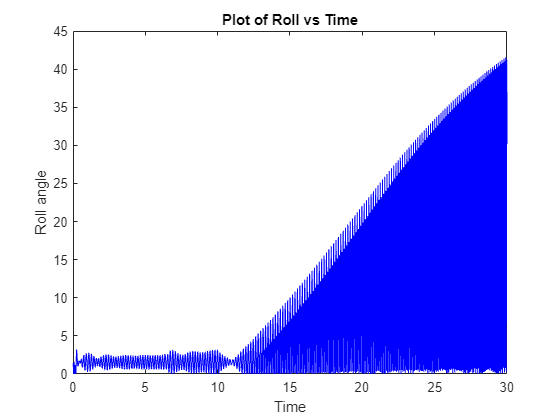


plot(roll_time,roll_5,'Color','b')
xlabel('Time')
ylabel('Roll angle')
title('Plot of Roll vs Time')

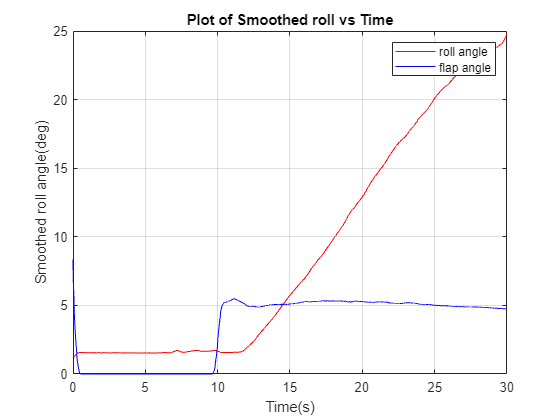

smoothed_data = smoothdata(roll_5,'gaussian',1000);
plot(roll_time,smoothed_data,'Color','r')
xlabel('Time(s)')
ylabel('Smoothed roll angle(deg)')
title('Plot of Smoothed roll vs Time')
grid on

flap_angle = abs(transpose(f.flap(2,:)));
flap_time = transpose(f.flap(1,:));
hold on

smoothed_data_flap = smoothdata(flap_angle,'gaussian',1000);
plot(flap_time,smoothed_data_flap,'Color','b')

legend('roll angle','flap angle')
hold off

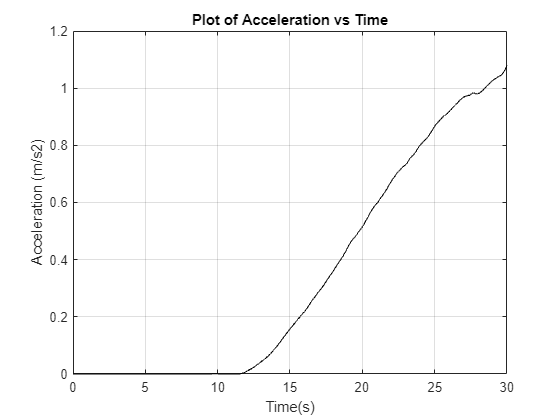

acc = transpose(acceleration.acc_y(2,:));
acc = abs(acc);
acc_time = transpose(acceleration.acc_y(1,:));
smoothed_data_acc = smoothdata(acc,'gaussian',1000);
plot(roll_time,smoothed_data_acc,'Color','k')
xlabel('Time(s)')
ylabel('Acceleration (m/s2)')
title('Plot of Acceleration vs Time')
grid on

% twenty = load ("20_deg.mat");
% roll_20 = transpose(twenty.attitude_wo_torque(2,:));
% 
% angles_20 = zeros(1,4);
% 
% for i = 1 : (time/6)-1
% 
%     array = roll_20(5341*i:(5341*i)+5341,:);
%     angles_20(:,i) = peak2peak(array);
% 
% end
% 
% disp(angles_20);